clear; close all; clc; 
%% preparing dataset 
load fisheriris 

species_num = grp2idx(species); 

species_num

species_num =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


% binary classification  
X = randn(100,10); 
X(:,[1,3,5,7]) = meas(1:100,:); % 1, 3, 5, 7 feature 

X

X =     5.1000    0.2719    3.5000    0.3404    1.4000   -1.0457    0.2000   -0.5278   -0.3742   -0.7075
    4.9000    1.4896    3.0000   -0.9632    1.4000    0.5057    0.2000    1.2416    0.6953   -1.3480
    4.7000    1.4371    3.2000    1.1139    1.3000    0.3320    0.2000   -0.1576    0.8776   -1.7543
    4.6000   -0.0276    3.1000   -1.5861    1.5000   -1.6354    0.2000   -1.3736    1.0336   -0.3638
    5.0000    0.9239    3.6000   -0.3918    1.4000   -1.9068    0.2000    0.8708    0.4198   -0.6271
    5.4000   -0.3213    3.9000   -1.4847    1.7000   -0.0404    0.4000   -1.5685    0.6011    0.4402
    4.6000    0.6611    3.4000   -0.3446    1.4000    0.6972    0.3000   -1.8443   -0.6740   -1.5026
    5.0000    1.9153    3.4000   -1.3239    1.5000    0.1688    0.2000    0.2884   -1.0952   -0.2082
    4.4000    0.1568    2.9000   -0.5748    1.4000   -1.5438    0.2000   -0.9509   -0.2676   -1.5051
    4.9000   -0.3005    3.1000   -0.7407    1.5000   -1.5518    0.1000   -0.9107    0.1

y = species_num(1:100); 
rand_num = randperm(size(X,1)); 
X_train = X(rand_num(1:round(0.8*length(rand_num))),:); 
y_train = y(rand_num(1:round(0.8*length(rand_num))),:); 

X_test = X(rand_num(round(0.8*length(rand_num))+1:end),:); 
y_test = y(rand_num(round(0.8*length(rand_num))+1:end),:); 


%% CV partition 

%% k-Fold Cross-Validation 

c = cvpartition(y_train,'k',5); 

%% feature selection 

opts = statset('display','iter'); 

classf = @(train_data, train_labels, test_data, test_labels)... 
    sum(predict(fitcsvm(train_data, train_labels,'KernelFunction','rbf'), test_data) ~= test_labels); 

[fs, history] = sequentialfs(classf, X_train, y_train, 'cv', c, 'options', opts,'nfeatures',2); 

Start forward sequential feature selection:
Initial columns included:  none
Columns that can not be included:  none
Step 1, added column 5, criterion value 0
Step 2, added column 1, criterion value 0
Final columns included:  1 5 


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |        0.25 |    0.095812 |        0.25 |        0.25 |       2.7551 |    0.0016563 |


|    2 | Accept |      0.4875 |    0.059425 |        0.25 |     0.26997 |     0.014178 |     0.053379 |


|    3 | Accept |      0.4875 |    0.058329 |        0.25 |     0.25002 |     0.008657 |       132.21 |


|    4 | Best   |           0 |    0.050417 |           0 |  2.9972e-05 |       610.17 |       1.7803 |


|    5 | Accept |           0 |    0.062302 |           0 | -0.00030132 |       999.79 |       2.1504 |


|    6 | Accept |        0.25 |    0.064003 |           0 |  -4.124e-06 |       999.58 |    0.0041521 |


|    7 | Accept |           0 |    0.060625 |           0 |  1.3426e-05 |       528.42 |       51.993 |


|    8 | Accept |           0 |    0.063076 |           0 |  -0.0042813 |       637.09 |       9.0013 |


|    9 | Accept |      0.4875 |    0.053023 |           0 | -4.1398e-05 |        977.4 |       981.15 |


|   10 | Accept |           0 |    0.067215 |           0 | -0.00010205 |       950.16 |       26.492 |


|   11 | Accept |           0 |    0.058965 |           0 |  -0.0001659 |       84.849 |       25.334 |


|   12 | Accept |           0 |    0.056113 |           0 | -0.00021621 |       77.891 |       4.0504 |


|   13 | Accept |           0 |    0.069548 |           0 | -0.00025983 |       902.59 |      0.29665 |


|   14 | Accept |           0 |      0.0549 |           0 | -0.00025319 |       967.64 |      0.57926 |


|   15 | Accept |           0 |    0.055165 |           0 | -0.00058841 |       94.269 |      0.37222 |


|   16 | Accept |           0 |    0.053149 |           0 |  -0.0010451 |       280.92 |       29.823 |


|   17 | Accept |           0 |    0.054347 |           0 |  -0.0010137 |       268.11 |      0.48273 |


|   18 | Accept |      0.0625 |    0.052776 |           0 |  -0.0012563 |       161.18 |      0.13889 |


|   19 | Accept |           0 |    0.055178 |           0 | -0.00090328 |      0.38087 |       1.8791 |


|   20 | Accept |           0 |    0.058776 |           0 |   -0.000943 |      0.66278 |       6.1967 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|   21 | Accept |           0 |    0.051095 |           0 |  -0.0010408 |       19.299 |       10.258 |


|   22 | Accept |      0.4875 |    0.058675 |           0 | -0.00066612 |    0.0010133 |       3.1457 |


|   23 | Accept |           0 |    0.055107 |           0 | -0.00071021 |       4.6755 |       1.4493 |


|   24 | Accept |           0 |    0.062763 |           0 | -0.00056278 |       1.2412 |       3.1865 |


|   25 | Accept |           0 |    0.054674 |           0 | -0.00073274 |        19.21 |      0.63579 |


|   26 | Accept |      0.0125 |     0.06223 |           0 | -0.00074524 |       3.7061 |       19.379 |


|   27 | Accept |           0 |    0.056051 |           0 | -0.00080475 |       1.3922 |       1.0515 |


|   28 | Accept |           0 |    0.058217 |           0 | -0.00080111 |       433.01 |       4.0491 |


|   29 | Accept |           0 |    0.055685 |           0 | -0.00073434 |       66.481 |      0.78812 |


|   30 | Accept |           0 |     0.05626 |           0 | -0.00076067 |       118.46 |       9.9126 |


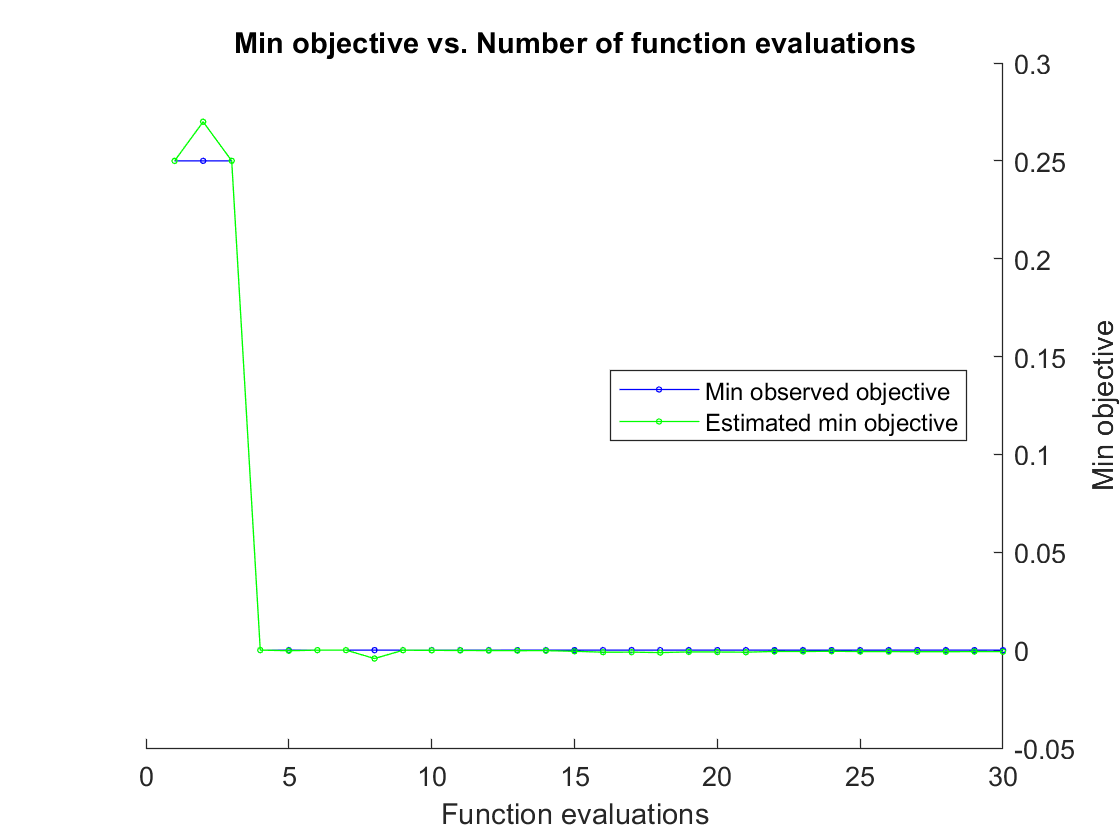

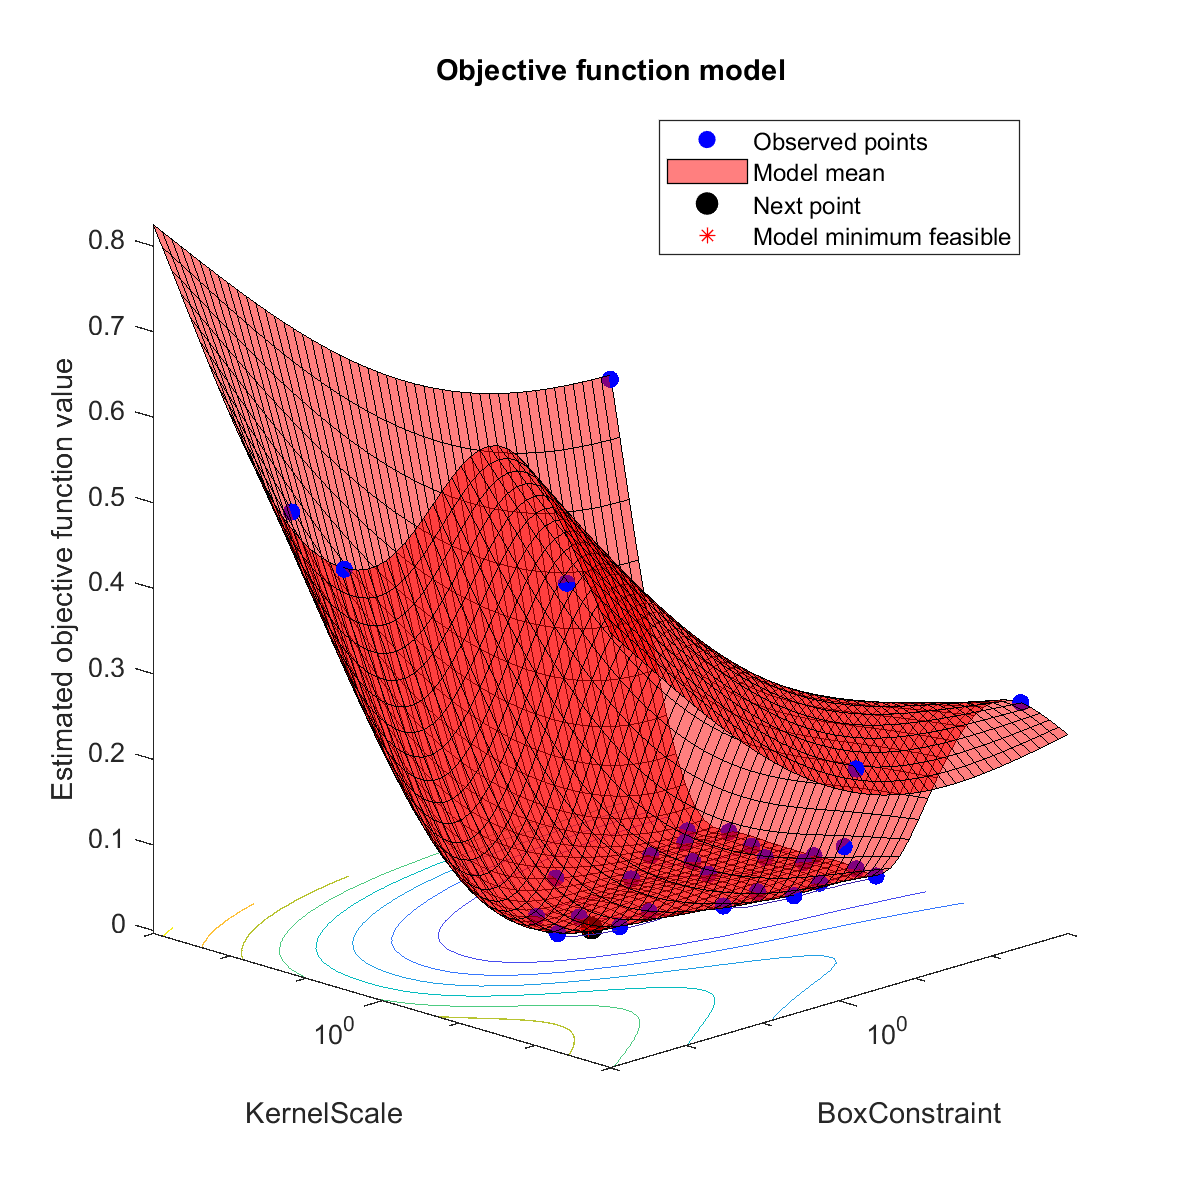


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 31.7593 seconds
Total objective function evaluation time: 1.7739

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       610.17          1.7803   

Observed objective function value = 0
Estimated objective function value = 0.00041142
Function evaluation time = 0.050417

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       268.11          0.48273  

Estimated objective function value = -0.00076067
Estimated function evaluation time = 0.056554



X_train_w_best_feature = X_train(:,fs); 

  

Md1 = fitcsvm(X_train_w_best_feature,y_train,'KernelFunction','rbf','OptimizeHyperparameters','auto', 'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName', ...
'expected-improvement-plus','ShowPlots',true));

%% Final test with test set 

X_test_w_best_feature = X_test(:,fs); 

test_accuracy_for_iter = sum((predict(Md1,X_test_w_best_feature) == y_test))/length(y_test)*100 

test_accuracy_for_iter = 100

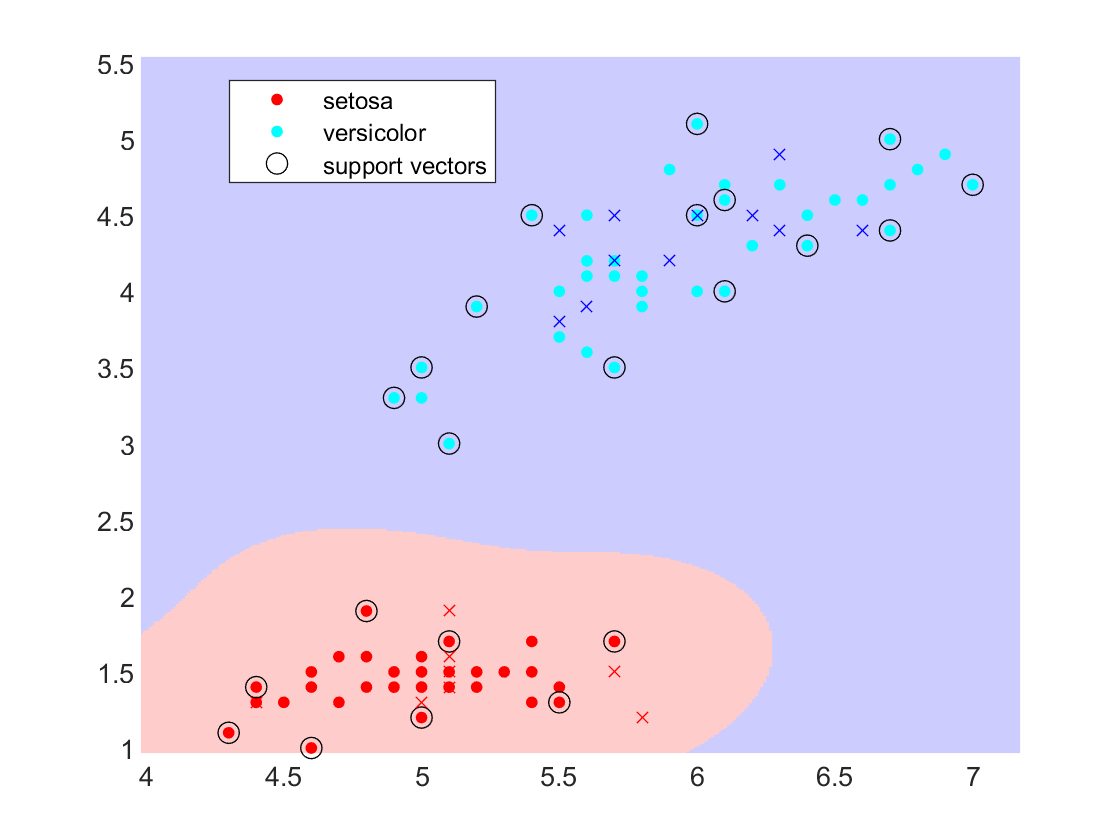

%% hyperplane  
figure; 
hgscatter = gscatter(X_train_w_best_feature(:,1),X_train_w_best_feature(:,2),y_train); 
hold on; 
h_sv=plot(Md1.SupportVectors(:,1),Md1.SupportVectors(:,2),'ko','markersize',8); 
  gscatter(X_test_w_best_feature(:,1),X_test_w_best_feature(:,2),y_test,'rb','xx') 

  % decision plane 
XLIMs = get(gca,'xlim'); 
YLIMs = get(gca,'ylim'); 

[xi,yi] = meshgrid([XLIMs(1):0.01:XLIMs(2)],[YLIMs(1):0.01:YLIMs(2)]); 
dd = [xi(:), yi(:)]; 
pred_mesh = predict(Md1, dd); 

redcolor = [1, 0.8, 0.8]; 
bluecolor = [0.8, 0.8, 1]; 

pos = find(pred_mesh == 1); 
h1 = plot(dd(pos,1), dd(pos,2),'s','color',redcolor,'Markersize',5,'MarkerEdgeColor',redcolor,'MarkerFaceColor',redcolor); 

pos = find(pred_mesh == 2); 
h2 = plot(dd(pos,1), dd(pos,2),'s','color',bluecolor,'Markersize',5,'MarkerEdgeColor',bluecolor,'MarkerFaceColor',bluecolor); 

uistack(h1,'bottom'); 
uistack(h2,'bottom'); 

legend([hgscatter;h_sv],{'setosa','versicolor','support vectors'}) 